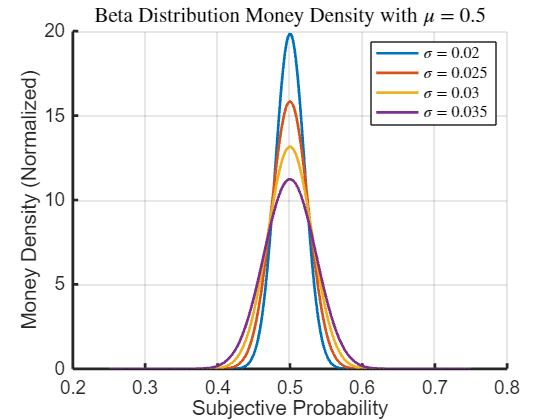

x_mesh = .25:.001:.75;
mu = .5;
sigma_mesh = .02:.005:.035;

figure
hold on
legend_labels = {};
for sigma = sigma_mesh
    y_mesh = modified_beta(x_mesh,mu,sigma);
    plot(x_mesh,y_mesh)
    legend_labels{length(legend_labels)+1} = sprintf('%s = %.2g','$\sigma$',sigma);
end
xlabel('Subjective Probability')
ylabel('Money Density (Normalized)')
title(sprintf('Beta Distribution Money Density with %s = %.2g','$\mu$',mu),'Interpreter','latex')
legend(legend_labels,'Interpreter','latex','FontSize',12)
sexy_plot